# Random Numbers: Reproducible and Random

% Make sure we have a process pool
delete(gcp("nocreate"));
p = parpool("Processes");

## Reproducible Random Numbers on Pool Workers

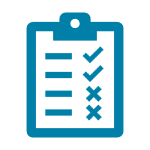Often if we run "monte-carlo" simulations we need to generate random numbers in parallel. Run the following block a few times. What does that tell you about how the default random number generator ("RNG") is handled automatically on the workers?

parfor k = 1:p.NumWorkers
    rand(1,7)
end

Great, we obviously have independent random streams on the workers per default, as these sets of random numbers do not repeat. But how do we achieve reproducibility?

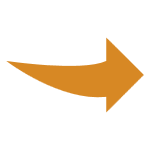**Let us try to use a spmd-block to set the random number generator to a specific seed and type on each worker.**

**MW: do we need to display or hide?**

**MW: why specify "threefry"?**

spmd
    rng(10,"threefry")
end

Take this paragraph and put it above the spmd code

We are using an [spmd block (single program, multiple data)](https://www.mathworks.com/help/parallel-computing/spmd.html) to execute the same block code on each worker of the pool. The `rng` function takes a seed and a generator type as input.

And then we let the workers generate random numbers in a parfor loop again

parfor k = 1:4
   rand(1,7) 
end

We obviously achieved reproducibility, but the random number streams are not independent any more.

Can you achieve both reproducible and independent random streams on the workers? Modify the code in the spmd-block to do that.

Hint: the workers are aware of their identity (called "rank") in the pool, you can query it for example with [`spmdIndex`](https://www.mathworks.com/help/parallel-computing/spmdindex.html).

spmd
    % CODE GOES HERE
end
parfor k = 1:4
   rand(1,7) 
end

In case you "misconfigured" the rng on the workers in your code experiments you can either restart the pool or reset the rng on the workers:

parfevalOnAll(@rng,0,"default");

## Random Number (Sub-)Streams on Workers

Take a look at the output of the parfor (running on workers) when you repeat the execution of the section. Is this fully reproducible? 

% Execute section more than once. Note that we reset the rng each time.
parfevalOnAll(@rng,0,"default");
parfor k = 1:8
    r(k) = rand;
end
r

Well, the numbers are the same, but the order changes sometimes. Remember: **the execution order of parfor in a pool is not determined** and cannot be relied on.

Can we modify the code so that the client and the workers generate the same sequence? For this, we need to use the [RandStream class](https://www.mathworks.com/help/matlab/ref/randstream.html) and chose a generator that supports Substreams:

sc = parallel.pool.Constant(RandStream('Threefry'));

A ["Constant"](https://www.mathworks.com/help/parallel-computing/parallel.pool.constant.html) is a variable that is pre-placed in each workers workspace in the pool... very useful concept. We place the common random number stream object there.

r = zeros(1,16);
parfor i = 1:16
    stream = sc.Value;
    stream.Substream = i; % fork an independent stream determined by the state of the parent
    r(i) = rand(stream);
end
r

When you execute the section multiple times you will find, that the numbers are now reproducible!

With this mechanism you can generate the same random sequence in parallel and on the client.

clientStream = RandStream('Threefry');
r2 = zeros(1,16);
for i = 1:16
    clientStream.Substream = i;
    r2(i) = rand(clientStream);
end
r2

## Random Numbers on GPU

gpu = gpuDevice;

rngtype = 'threefry';

% Set the random number generator and seed on GPU and CPU
gpurng(0, rngtype);
rng(0, rngtype);

We now generate a large number of random numbers (as in the GPU section we time the second execution to disregard overhead):

N = 1e4; % Size of Random matrix (NxN)

A = gpuArray.rand(N);
tic
A = gpuArray.rand(N);
wait(gpu)
gputime = toc;

Same thing on the CPU:

B = rand(N);
tic
B = rand(N);
cputime = toc;

disp("GPU speedup: " + num2str(cputime/gputime) + "x")

As you can see it can be very beneficial to generate large amounts of random numbers on the GPU (at least if you plan to use them on the device).

Explore whether generating the random array in the device memory as "single" improves performance even further!

% CODE GOES HERE
%...
tic
%...
gpusingletime = toc;
disp("Single vs. Double speedup (on GPU): " + num2str(gputime/gpusingletime) + "x")

See, sometimes it is not so easy... 

Speculate about possible underlying reasons for your finding!